% Load all images from folder
imds = datastore("Images\calibrated\*.jpg");
imgs = readall(imds);

% Display text
disp("There are: " + length(imgs) + " images.")

There are: 6740 images.



% Write images back as another name
%imwrite(img01, "Images\calibrated\mars01.jpg")
%imwrite(img02, "Images\calibrated\mars02.jpg")
%imwrite(rover, 'Images\calibrated\rover.jpg');

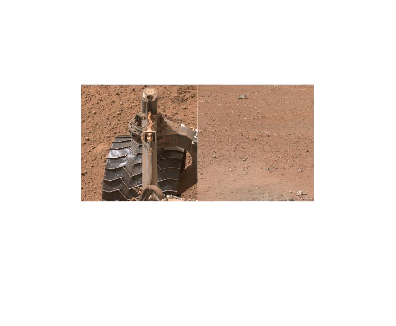

% Load rover and mars images
rover = imread('Images\calibrated\rover.jpg');
mars = imread('Images\calibrated\mars01.jpg');

% Show the pair
imshowpair(rover, mars, "montage")

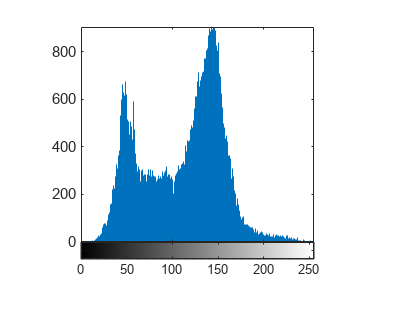

% Convert to grayscale
grayRover = rgb2gray(rover);

% View intensity plot
imhist(grayRover)


% Create mask
roverMask = grayRover < 130

roverMask = 256×256 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   1   1   0   0   0   0   0   0   0   1   0   0   1   0   0   1   1   0   1   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   1   1   0   1   0   1   0   0   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1
   0   1   1   0   0   0   0   0   0   1   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   1   1   0   0   1   1   1   0   0
   0   1   1   1   0   0   0   0   0   1   1   0   1   1   0   0   0   0   1   1   1   1   1   0   0   0   0   0   1   1   0   0   0   0   1   0   0   0   0   0  

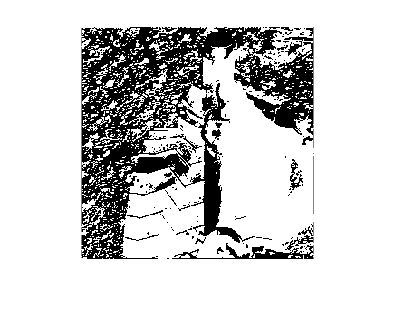

imshow(roverMask)

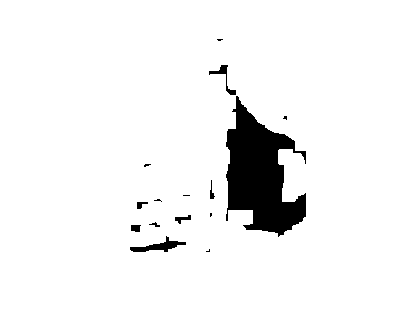


%filtRover = rescale(stdfilt(grayRover, true(15)));
% Attempt to segment
roverRNG = rangefilt(roverMask, true(15));
imshow(roverRNG)

% Convert to grayscale
roverGray = rgb2gray(rover);
marsGray = rgb2gray(mars);

% Take look at different scales to try other segementations
[l,a,b] = imsplit(rgb2lab(rover));
[ml,ma,mb] = imsplit(rgb2lab(mars));

% Binarize, convert to black and white
roverBW = imbinarize(roverGray, "adaptive");
marsBW = imbinarize(marsGray, "adaptive");

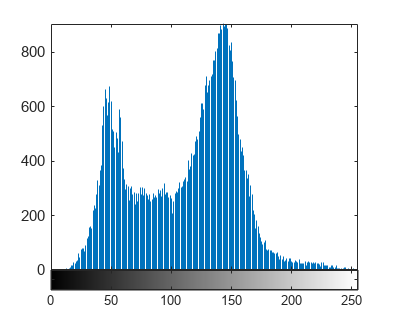

% See if we can find where to crop
imhist(roverGray)

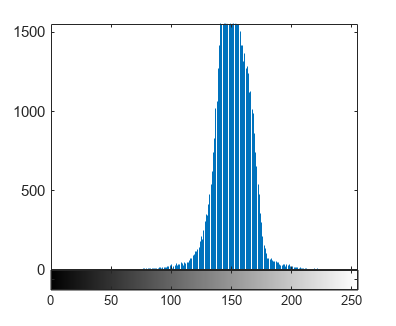

imhist(marsGray)

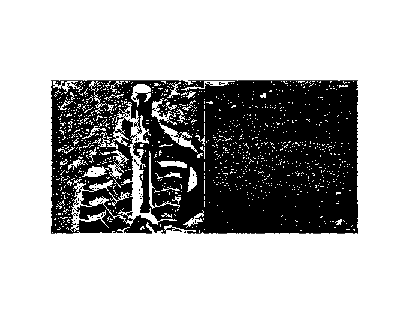

% Look at them side by side
imshowpair(roverBW, marsBW, "montage")

% Read images
img01 = imread("Images\calibrated\mars01.jpg");
img02 = imread("Images\calibrated\mars02.jpg");

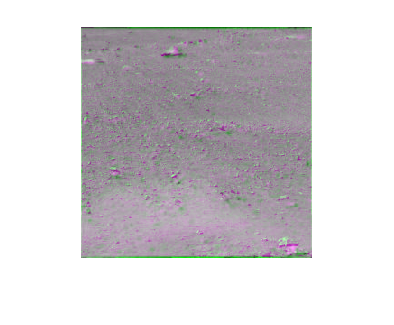

% Converting to double to perform calculations
marsDbl = im2double(img01);

% Convert to grayscale
marsGray1 = im2gray(img01);
marsGray2 = im2gray(img02);

% Display
imshowpair(marsGray1, marsGray2)

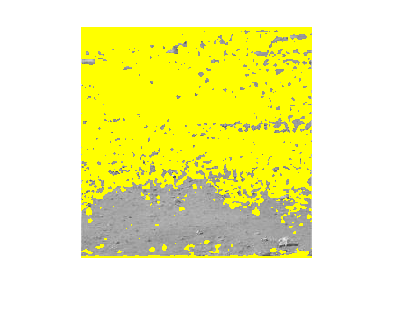

% Thresholding 
thresh_mg2 = imbinarize(marsGray2);
thresh_mg1 = imbinarize(marsGray2);

% Overlay
lay1 = imoverlay(marsGray1, ~thresh_mg1); 
lay2 = imoverlay(marsGray2, thresh_mg2);

imshow(lay1)

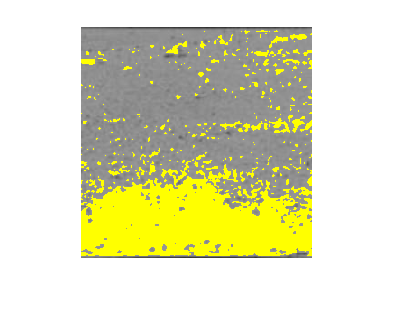

imshow(lay2)

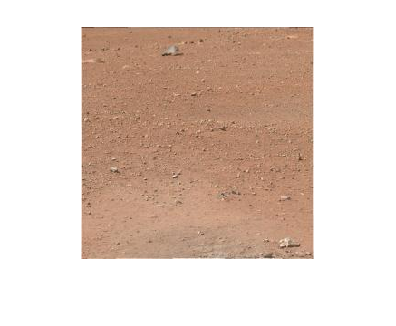

mars = imread("Images\calibrated\mars01.jpg");
imshow(mars)

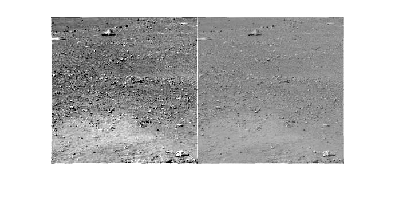

grayMars = im2gray(mars);
marsAdj = imadjust(grayMars);
imshowpair(marsAdj, grayMars, "montage")

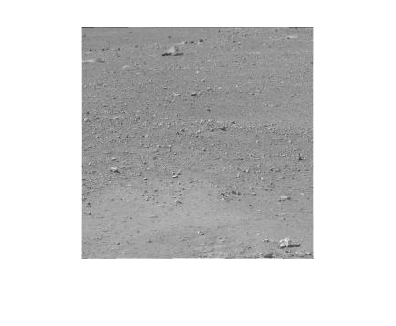

imshow(grayMars)

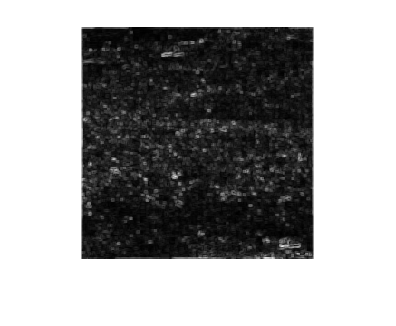

filtMars = rescale(stdfilt(grayMars));
imshow(filtMars)

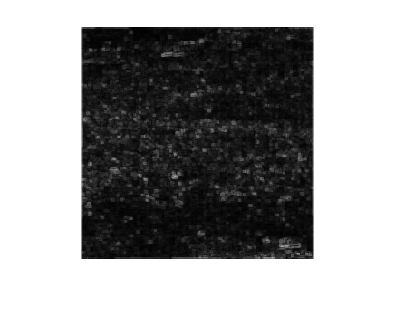

RNGMars = rangefilt(grayMars, true(3));
imshow(RNGMars)

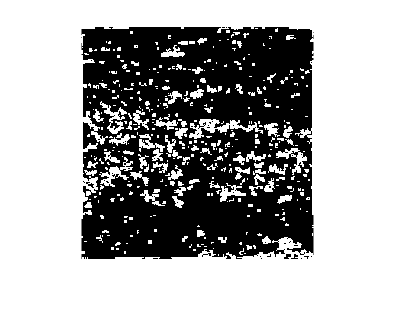

BWMars = imbinarize(RNGMars);
imshow(BWMars)

BWmars = imbinarize(grayMars);
%filledMars = imfill(BWmars);
rocks = bwpropfilt(BWmars,"area", [0,10])

rocks = 256×256 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

CCrocks = bwconncomp(rocks)

CCrocks = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 1524
    PixelIdxList: {1×1524 cell}


numRocks = CCrocks.NumObjects;

numRocks = 1524

disp("There are ~" + numRocks + " rocks in this photo.")

There are ~1524 rocks in this photo.


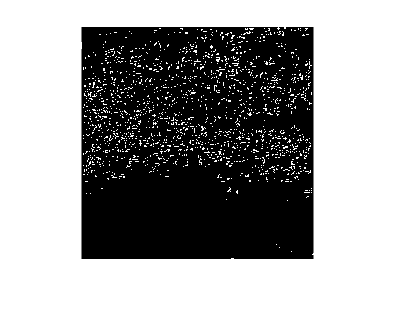

imshow(rocks)

% Erode and dialate images to smooth masking
closeMars = imclose(BWMars, strel("disk",1));
cleanMars = imopen(closeMars, strel("disk", 1))

cleanMars = 256×256 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

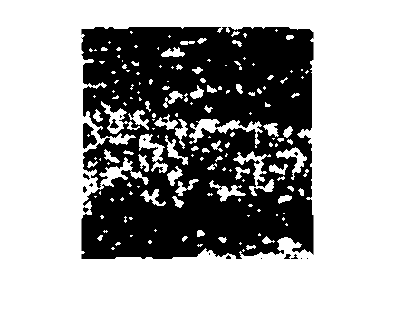

imshow(cleanMars)

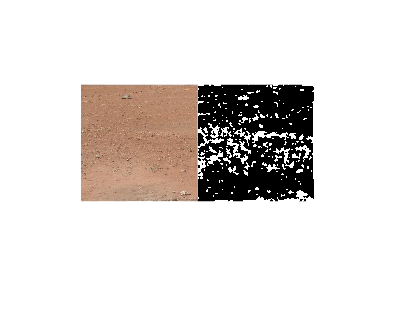

imshowpair(mars, cleanMars, "montage")

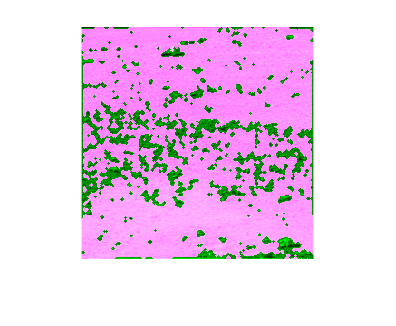

imshowpair(mars, ~cleanMars)

function [rockCount] = countRocks(img)
    % This function counts the number of rocks in an image
    grayImg = rgb2gray(img);
    BWimg = imbinarize(grayImg);
    rocks = bwpropfilt(BWimg,"area", [0,10])
    CCrocks = bwconncomp(rocks)
    numRocks = CCrocks.NumObjects;
    %disp("There are ~" + numRocks + " rocks in this photo.")
    rockCount = numRocks
end